
clear;

cs = crystalSymmetry('cubic');
ss = specimenSymmetry('mmm');

[eul_ini] = grid2euler(0, 45, 0,10,2.5);

eul_ini =    -0.1745    0.6109   -0.1745
   -0.1745    0.6545   -0.1745
   -0.1745    0.6981   -0.1745
   -0.1745    0.7418   -0.1745
   -0.1745    0.7854   -0.1745
   -0.1745    0.8290   -0.1745
   -0.1745    0.8727   -0.1745
   -0.1745    0.9163   -0.1745
   -0.1745    0.9599   -0.1745
   -0.1309    0.6109   -0.1745


Now calculate the orientation matrix

gmatrix0 = rotation('Euler',eul_ini);
% gmatrix0 = rotation('Euler',[phi1 , phi , phi2]*degree);

f (full), p (only partial), fp (full+partial), ft(full+twin)


slip_type = 'f';

 0 (Full), 1 (Lath), 2 (PanCake)

constraints = 0;
max_strain = .02;
incr_e = 0.02;

0 (minVar), 1(maxVar), 2(minPlasticSpin), 3(wintenberger) 


criteria = 0;

tic

%% Initializing the cost matrix according to type of slip mode
c = [1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1,1];
% full slip: n = 1-12,25-36 
% partial slip: n=13-24,37-48
% twin:n=13-24

switch slip_type
    case {'F', 'f'} % only perfect slip
        n = [13:24,37:48];
        c(n)=1e4; % All partial modes are made costlier        
    case {'P','p'} % only partial slip
        n = [1:12,25:36];
        c(n)=1e4; % All perfect modes are made costlier
    case {'FP','fp','Fp','fP'} %both perfect and partial slips
        
    case {'FT','ft','Ft','fT'}
        n = 37:48;
        c(n)=1e4; % All - partial modes are made costlier        
    otherwise
        warning('Unexpected slip type.\n {Default perfect slip is applied');        
 end
        
% criteria = 'minplasticspin';

gmatrix = gmatrix0;
lg =  length(gmatrix);
e_ext= [1,0,0;0,0,0;0,0,-1];
b = zeros(5,lg);
n_steps = max_strain/incr_e;
new_gmatrix(:,1) = gmatrix;

%% Calculation Block

for j=1:1:n_steps

for i=1:1:lg 
    DCMtrx = matrix(gmatrix(i));  
    e_grain=DCMtrx'*e_ext*DCMtrx; 
    b = [e_grain(1,1);e_grain(2,2);2*e_grain(2,3);2*e_grain(1,3);2*e_grain(1,2)]; 
    AllSolutions = calcLPSolution(b,c); 
    [spin, UniqueSolution] = calculate_spin(AllSolutions,criteria);
    spin = incr_e*spin;
    gmatrix(i) = applySpin(-spin,DCMtrx); 
    new_gmatrix(i,j+1) = gmatrix(i);
end
end


eul_fin = Euler(new_gmatrix(:,(j+1)));%/degree;



o_ini = orientation('Euler',eul_ini,cs,ss);%.project2FundamentalRegion;
o_fin = orientation('Euler',eul_fin,cs,ss);%.project2FundamentalRegion;

del_phi1 = (o_fin.phi1 - o_ini.phi1)/degree;
del_Phi = (o_fin.Phi - o_ini.Phi)/degree;
del_phi2 = (o_fin.phi2 - o_ini.phi2)/degree;

toc

Elapsed time is 12.810546 seconds.


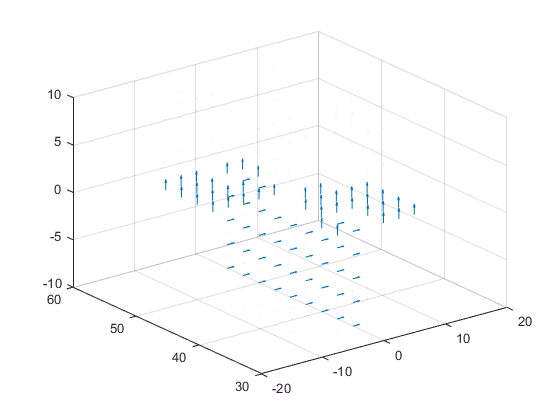

quiver3(eul_ini(:,1)/degree,eul_ini(:,2)/degree,eul_ini(:,3)/degree,del_phi1,del_Phi,del_phi2)